# Kersbergen et al, 2022

% Figure 1C, D, Supplement figure 2 (P7)

% ISC whole cell v clamp recordings, P7
% 2.5K external, Atp -, gtp + internal, phys temp (32-34C) 
% performed by CJK and TAB

[tectatm1 time1] = loadPclampData('19n13012.abf');

opening 19n13012.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 603.1 s ~ 10 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 23 MB


[tectatm2 time2] = loadPclampData('19n13023.abf');

opening 19n13023.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 604.9 s ~ 10 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 23 MB


[tectatm3 time3] = loadPclampData('2019_11_13_0011_adjusted.abf');

opening 2019_11_13_0011_adjusted.abf..
**** available channels:
    'IN 1'

data were acquired in gap-free mode
total length of recording: 601.5 s ~ 10 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 23 MB


[tectatm4 time4] = loadPclampData('2019_11_26_0007_adjusted.abf');

opening 2019_11_26_0007_adjusted.abf..
**** available channels:
    'IN 1'

data were acquired in gap-free mode
total length of recording: 614.0 s ~ 10 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 23 MB


[tectatm5 time5] = loadPclampData('2020_08_09_0003.abf'); % uncoupled at end of recording, poor

opening 2020_08_09_0003.abf..
**** available channels:
    'IN 1'

data were acquired in gap-free mode
total length of recording: 648.3 s ~ 11 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 25 MB


[tectatm6 time6] = loadPclampData('2020_08_09_0015.abf'); % lots of drifting, poor

opening 2020_08_09_0015.abf..
**** available channels:
    'IN 1'

data were acquired in gap-free mode
total length of recording: 816.2 s ~ 14 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 31 MB



% control - tmem16a flfl 
[tmem1 timeCon1] = loadPclampData('19n13008.abf'); 

opening 19n13008.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 680.5 s ~ 11 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 26 MB


[tmem2 timeCon2] = loadPclampData('19n13016.abf');

opening 19n13016.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 611.9 s ~ 10 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 23 MB


[tmem3 timeCon3] = loadPclampData('19n13027.abf');

opening 19n13027.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 633.0 s ~ 11 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 24 MB


[tmem4 timeCon4] = loadPclampData('19n13031.abf');

opening 19n13031.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 600.4 s ~ 10 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 23 MB


[tmem5 timeCon5] = loadPclampData('2019_11_13_0002_adjusted.abf'); 

opening 2019_11_13_0002_adjusted.abf..
**** available channels:
    'IN 1'

data were acquired in gap-free mode
total length of recording: 625.9 s ~ 10 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 24 MB


[tmem6 timeCon6] = loadPclampData('2020_01_07_0015_adjusted.abf'); 

opening 2020_01_07_0015_adjusted.abf..
**** available channels:
    'IN 1'

data were acquired in gap-free mode
total length of recording: 607.9 s ~ 10 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 23 MB


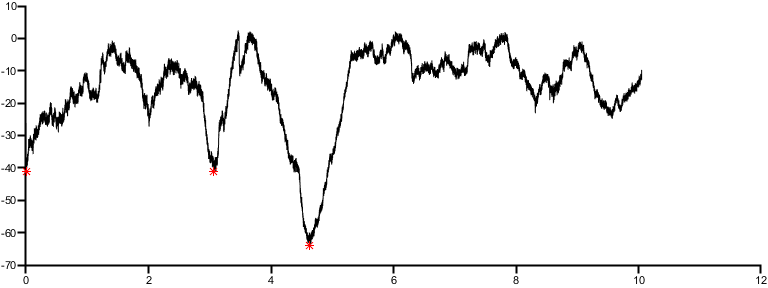

meanFreqISC1 = 0.2985

meanAmpISC1 = -48.7614

chargeTrans1 = 15.4891


% baseline correction
tectatm1 = msbackadj(time1, -tectatm1, 'WindowSize', 60,'StepSize',30);
tectatm2 = msbackadj(time2, -tectatm2, 'WindowSize', 60,'StepSize',30);
tectatm5 = msbackadj(time5, -tectatm5, 'WindowSize', 60,'StepSize',30);
tectatm6 = msbackadj(time6, -tectatm6, 'WindowSize', 60,'StepSize',30);

tmem1 = msbackadj(timeCon1, -tmem1, 'WindowSize', 60,'StepSize',30);
tmem2 = msbackadj(timeCon2, -tmem2, 'WindowSize', 60,'StepSize',30);
tmem3 = msbackadj(timeCon3, -tmem3, 'WindowSize', 60,'StepSize',30);
tmem4 = msbackadj(timeCon4, -tmem4, 'WindowSize', 60,'StepSize',30);

[meanFreqISC1,meanAmpISC1,chargeTrans1] = freqAmpISCbaseline(-tectatm1, time1)

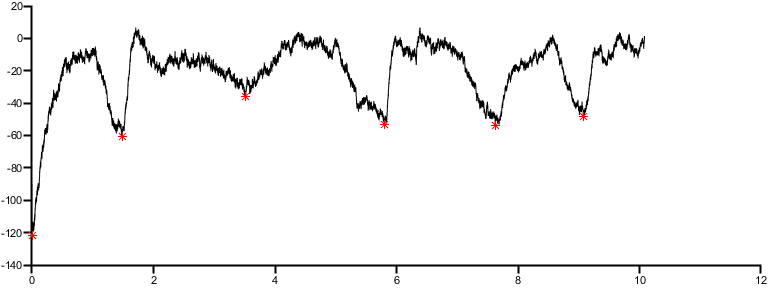

meanFreqISC2 = 0.5951

meanAmpISC2 = -62.1863

chargeTrans2 = 20.0750

[meanFreqISC2,meanAmpISC2,chargeTrans2] = freqAmpISCbaseline(-tectatm2, time2)

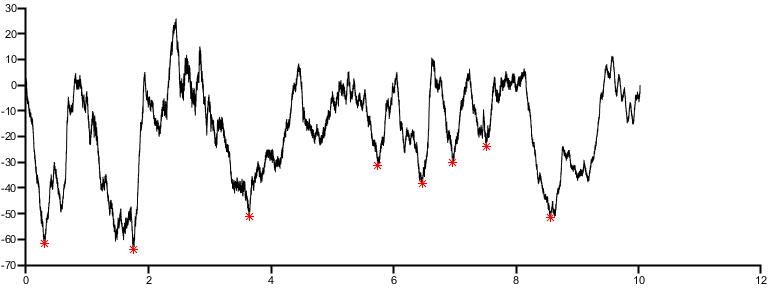

meanFreqISC3 = 0.7980

meanAmpISC3 = -43.9904

chargeTrans3 = 18.1280

[meanFreqISC3,meanAmpISC3,chargeTrans3] = freqAmpISCbaseline(tectatm3, time3)

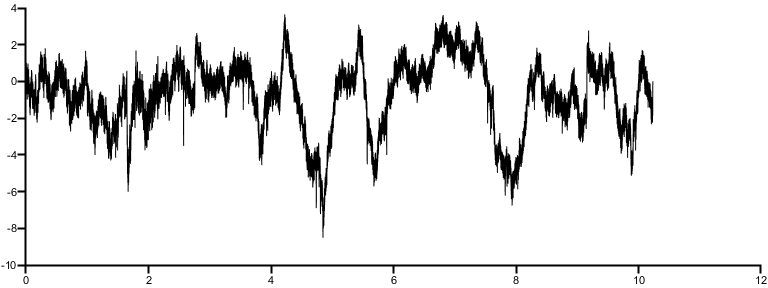

meanFreqISC4 = 0

meanAmpISC4 = 0

chargeTrans4 = 0.7603

[meanFreqISC4,meanAmpISC4,chargeTrans4] = freqAmpISCbaseline(tectatm4, time4)

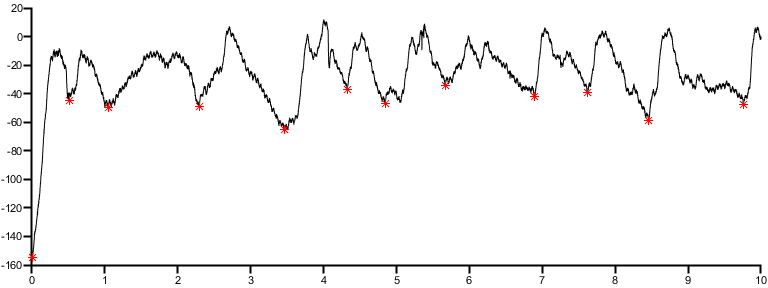

meanFreqISC5 = 1.2000

meanAmpISC5 = -55.7595

chargeTrans5 = 25.7807

[meanFreqISC5,meanAmpISC5,chargeTrans5] = freqAmpISCbaseline(-tectatm5(1:3000000), time5(1:3000000))

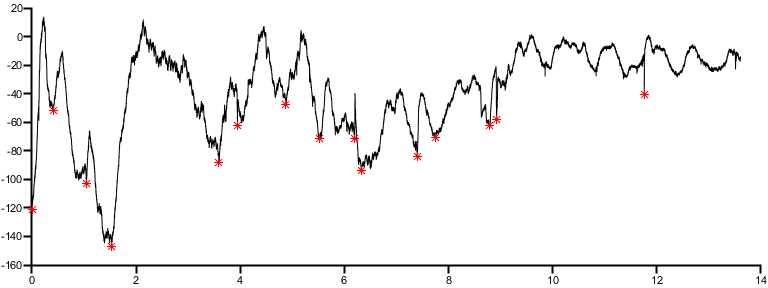

meanFreqISC6 = 1.1027

meanAmpISC6 = -78.2485

chargeTrans6 = 37.4126

[meanFreqISC6,meanAmpISC6,chargeTrans6] = freqAmpISCbaseline(-tectatm6, time6)

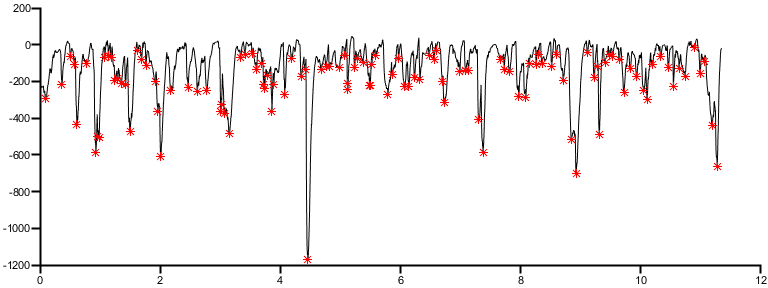

ConmeanFreqISC1 = 10.1389

ConmeanAmpISC1 = -211.6133

ConchargeTrans1 = 119.0414


tectatmFreq = [meanFreqISC1,meanFreqISC2,meanFreqISC3,meanFreqISC4,meanFreqISC5,meanFreqISC6];
tectatmAmp = abs([meanAmpISC1,meanAmpISC2,meanAmpISC3,meanAmpISC4,meanAmpISC5,meanAmpISC6]);
tectatmCharge = abs([chargeTrans1,chargeTrans2,chargeTrans3,chargeTrans4,chargeTrans5,chargeTrans6]);

[ConmeanFreqISC1,ConmeanAmpISC1,ConchargeTrans1] = freqAmpISCbaseline(-tmem1, timeCon1)

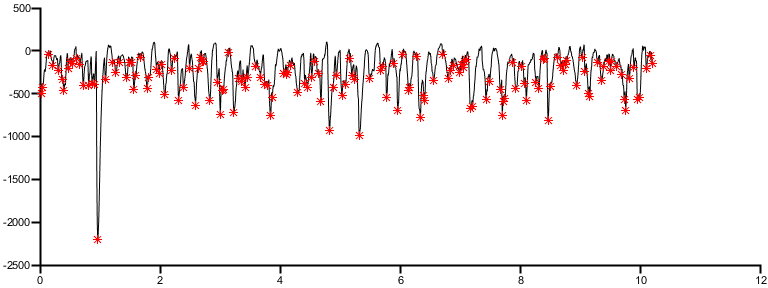

ConmeanFreqISC2 = 14.7071

ConmeanAmpISC2 = -346.3768

ConchargeTrans2 = 211.9768

[ConmeanFreqISC2,ConmeanAmpISC2,ConchargeTrans2] = freqAmpISCbaseline(-tmem2, timeCon2)

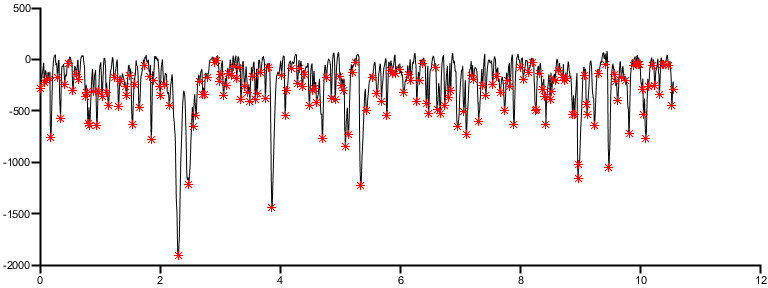

ConmeanFreqISC3 = 17.2498

ConmeanAmpISC3 = -341.8705

ConchargeTrans3 = 218.4022

[ConmeanFreqISC3,ConmeanAmpISC3,ConchargeTrans3] = freqAmpISCbaseline(-tmem3, timeCon3)

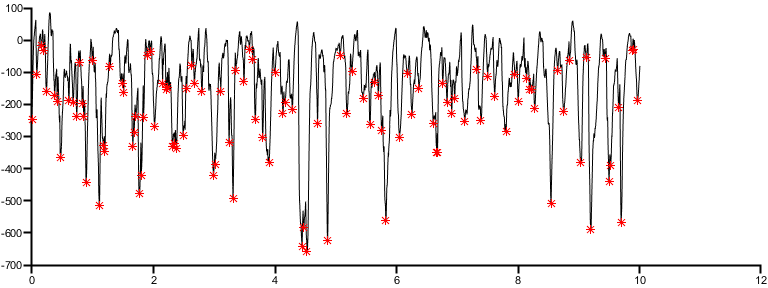

ConmeanFreqISC4 = 10.9927

ConmeanAmpISC4 = -236.3569

ConchargeTrans4 = 133.5842

[ConmeanFreqISC4,ConmeanAmpISC4,ConchargeTrans4] = freqAmpISCbaseline(-tmem4, timeCon4)

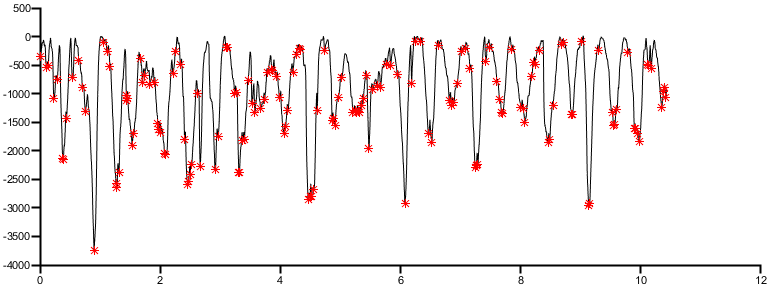

ConmeanFreqISC5 = 14.9552

ConmeanAmpISC5 = -1.2213e+03

ConchargeTrans5 = 876.7535

[ConmeanFreqISC5,ConmeanAmpISC5,ConchargeTrans5] = freqAmpISCbaseline(tmem5, timeCon5)

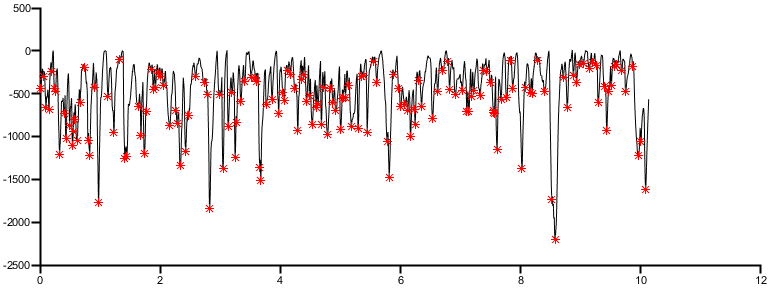

ConmeanFreqISC6 = 15.5960

ConmeanAmpISC6 = -649.8951

ConchargeTrans6 = 444.8005

[ConmeanFreqISC6,ConmeanAmpISC6,ConchargeTrans6] = freqAmpISCbaseline(tmem6, timeCon6)


ConFreq = [ConmeanFreqISC1,ConmeanFreqISC2,ConmeanFreqISC3,ConmeanFreqISC4,ConmeanFreqISC5,ConmeanFreqISC6];
ConAmp = abs([ConmeanAmpISC1,ConmeanAmpISC2,ConmeanAmpISC3,ConmeanAmpISC4,ConmeanAmpISC5,ConmeanAmpISC6]);
ConCharge = abs([ConchargeTrans1,ConchargeTrans2,ConchargeTrans3,ConchargeTrans4,ConchargeTrans5,ConchargeTrans6,]);

conditions = {'Control','cKO'};
ylbl1 = 'Events per minute';
dim = [1 2];
[fig1P7 h1 p1] = compare2(ConFreq,tectatmFreq,conditions,ylbl1,dim);
h1

h1 = 4.1338e-07

 ylim([0 35]);
 p1

p1 = 1

 yticks([0 5 10 15 20 25 30 35])
 
ylbl2 = 'Mean amplitude (-pA)';
[fig2 h2 p2]  = compare2(ConAmp,tectatmAmp,conditions,ylbl2,dim);
h2

h2 = 0.0167

 ylim([0 1500]);
  [h p stats] = ttest2(ConAmp,tectatmAmp,'Vartype','unequal')

h = 1

p = 0.0346

stats =    48.4350  857.7314


ylbl3 = 'Normalized Charge (-pA)';
[fig3 h3 p3] = compare2(ConCharge,tectatmCharge,conditions,ylbl3,dim);
h3

h3 = 0.0243

 ylim([0 1000]);
 [h p stats] = ttest2(ConCharge,tectatmCharge,'Vartype','unequal')

h = 1

p = 0.0452

stats =     9.8457  619.1252


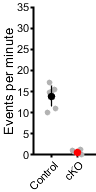

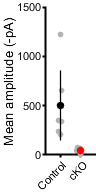

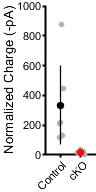

 
subP = handleTheSubplot({fig1P7,fig2,fig3},[1 3]);

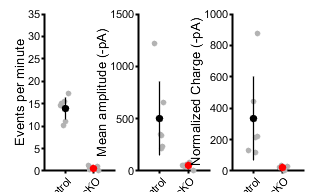

figQuality(subP,gca,[3.5 2])


[CorrP CorrA h] = fdr_BH([h1,h2,h3],0.05)

CorrP =     0.0000    0.0243    0.0243


CorrA =     0.0167    0.0333    0.0500


h = 3×1 logical array
   1
   1
   1


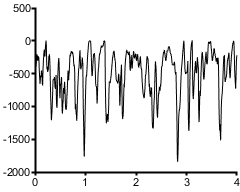


% Representative displays
% control
figure;
tmem6 = medfilt1(tmem6,100);
plot(timeCon6()/60,tmem6(),'k','LineWidth', 1)
ylim([-2000 500]);
xlim([0 4])
figQuality(gcf,gca,[2.5 2])

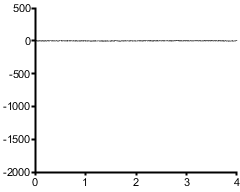


% tecta-cre; tmem16a fl/fl
figure;
tectatm4 = medfilt1(tectatm4,100);
plot(time4()/60,tectatm4(),'k','LineWidth', 1)
ylim([-2000 500]);
xlim([0 4])
figQuality(gcf,gca,[2.5 2])